## **2D Kalman Filter**

%problem attached: https://cecas.clemson.edu/~ahoover/ece854/labs/lab4-KF.pdf

clc;
clear;

%getting the measurement data
urlwrite("https://cecas.clemson.edu/ahoover/ece854/labs/2D-UWB-data.txt","measurement_Q2.txt")

ans = 'C:\Users\shubh\OneDrive - Clemson University\CUICAR\fall_2022\ece8540\assignments\lab4\measurement_Q2.txt'

inp_filename = "measurement_Q2.txt"

inp_filename = "measurement_Q2.txt"

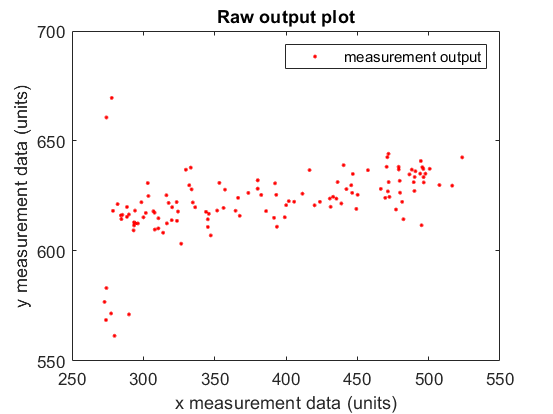

fid = fopen(inp_filename); % open the file
iCtr = 0;
yy_q2=[];
yx_q2=[];
while ~feof(fid) % loop over the following until the end of the file is reached.
  line = fgets(fid); % read in one line
  data1 = strsplit(line);
  yx_q2(end+1) = str2double(data1(1));
  yx_q2=yx_q2';
  yy_q2(end+1) = str2double(data1(2));
  yy_q2=yy_q2';
end

figure(1)
plot(yx_q2,yy_q2,'.r')
ylabel('y measurement data (units)');
xlabel('x measurement data (units)');
title('Raw output plot');
ylim([550 700])
legend('measurement output','location','northeast');



%assuming a time array corresponding with measurement data with a frequency of 1Hz
time_q2=(1:0.5:length(yy_q2)/2);

    "done"



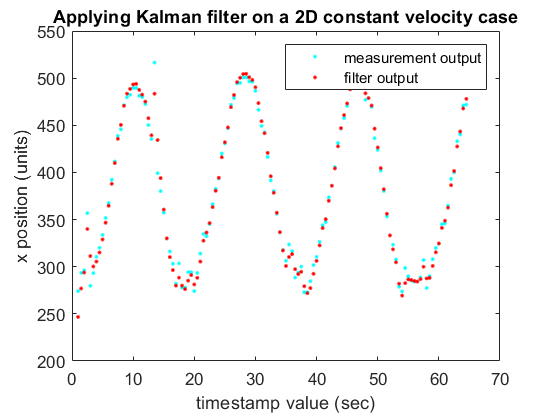


%case1

%position in x
xx_q2=zeros(length(yx_q2),2);
xx_q2(1,1:end) = yx_q2(1)*0.9;
%velocity in x
xx_dot_q2 = zeros(length(yx_q2),2);
xx_dot_q2(1,1:end) = yx_q2(2)-yx_q2(1);
%position in y
xy_q2=zeros(length(yy_q2),2);
xy_q2(1,1:end) = yy_q2(1)*0.9;
%velocity in y
xy_dot_q2 = zeros(length(yy_q2),2);
xy_dot_q2(1,1:end) = yy_q2(2)-yy_q2(1);

var_xx_dot_q2 = 1;
var_xy_dot_q2 = 1;
%S_prev_q2 = [0, 0, 0, 0; 0, var_xx_dot_q2^2, 0, 0; 0, 0, 0, 0; 0, 0, 0, var_xy_dot_q2^2];  
S_prev_q2 = eye(4,4);                   %4*4 matrix
S_next_q2 = 0;                          %4*4 matrix
R_q2 = [1 0.01; 0.01 1];                %2*1 matrix
M_q2 = [1, 0, 0, 0; 0, 0, 1, 0];        %2*4 matrix
Q_q2 = [0, 0, 0, 0; 0, var_xx_dot_q2^2, 0, 0.1; 0, 0, 0, 0; 0, 0.1, 0, var_xy_dot_q2^2];       %4*4 matrix

Kalman_filter(xx_q2,xx_dot_q2,xy_q2,xy_dot_q2,yx_q2,yy_q2,time_q2,S_prev_q2,S_next_q2,R_q2,M_q2,Q_q2,2)


%case2: decreasing measurement noise

%position in x
xx2_q2=zeros(length(yx_q2),2);
xx2_q2(1,1:end) = yx_q2(1)*0.9;
%velocity in x
xx2_dot_q2 = zeros(length(yx_q2),2);
xx2_dot_q2(1,1:end) = yx_q2(2)-yx_q2(1);
%position in y
xy2_q2=zeros(length(yy_q2),2);
xy2_q2(1,1:end) = yy_q2(1)*0.9;
%velocity in y
xy2_dot_q2 = zeros(length(yy_q2),2);
xy2_dot_q2(1,1:end) = yy_q2(2)-yy_q2(1);

vaR2_xx2_dot_q2 = 0.5;
vaR2_xy2_dot_q2 = 0.5;
%S_prev_q2 = [0, 0, 0, 0; 0, vaR2_xx2_dot_q2^2, 0, 0; 0, 0, 0, 0; 0, 0, 0, vaR2_xy2_dot_q2^2];  
S_prev_q2 = eye(4,4);                   %4*4 matrix
S_next_q2 = 0;                          %4*4 matrix
R2_q2 = [0.1, 0.001; 0.001,0.10];     %2*1 matrix
M2_q2 = [1, 0, 0, 0; 0, 0, 1, 0];       %2*4 matrix
Q2_q2 = [0, 0, 0, 0; 0, vaR2_xx2_dot_q2^2, 0, 0.1; 0, 0, 0, 0; 0, 0.1, 0, vaR2_xy2_dot_q2^2];       %4*4 matrix

%Kalman_filter(xx2_q2,xx2_dot_q2,xy2_q2,xy2_dot_q2,yx_q2,yy_q2,time_q2,S_prev_q2,S_next_q2,R2_q2,M2_q2,Q2_q2,4)

function Kalman_filter(xx_q2,xx_dot_q2,xy_q2,xy_dot_q2,yx_q2,yy_q2,time_q2,S_prev_q2,S_next_q2,R_q2,M_q2,Q_q2,fignum)
    for i=2:1:length(yx_q2)-1
        %step 1: Predict next state
        phi_q2 = [1, time_q2(i)-time_q2(i-1), 0, 0; 0, 1, 0, 0;0, 0, 1, time_q2(i)-time_q2(i-1) ; 0, 0, 0, 1];            %4*4 matrix
        X_pred_q2 = phi_q2*([xx_q2(i-1,2),xx_dot_q2(i-1,2),xy_q2(i-1,2),xy_dot_q2(i-1,2)]');
        %placing predictions in the state variable array
        xx_q2(i,1)=X_pred_q2(1);
        xx_dot_q2(i,1)=X_pred_q2(2);
        xy_q2(i,1)=X_pred_q2(3);
        xy_dot_q2(i,1)=X_pred_q2(4);
        
        %step 2: predict next state covariance
        S_next_q2 = phi_q2*S_prev_q2*(phi_q2') + Q_q2;
    
        %step 3: obtain measurements (there as input)
        Y_q2 = [yx_q2(i); yy_q2(i)];
    
        %step 4: calculate Kalman Gain
        K_q2 = S_next_q2*(M_q2)'*((M_q2*S_next_q2*(M_q2)'+ R_q2)^-1);
    
        %step 5: update state
        X_upd_q2 = X_pred_q2 + K_q2*(Y_q2-(M_q2*X_pred_q2));
        %placing predictions in the state variable array
        xx_q2(i,2)=X_upd_q2(1);
        xx_dot_q2(i,2)=X_upd_q2(2);
        xy_q2(i,2)=X_upd_q2(3);
        xy_dot_q2(i,2)=X_upd_q2(4);
    
        %step 6: update state covariance
        S_prev_q2 = [eye(4,4) - K_q2*M_q2]*S_next_q2;
    end
    display("done");


    figure(fignum)
    plot(time_q2,yx_q2(1:end-1),'.c')
    ylabel('x position (units)');
    xlabel('timestamp value (sec)');
    hold on;
    plot(time_q2,xx_q2(1:end-1,2),'.r');
    title('Applying Kalman filter on a 2D constant velocity case');
    legend('measurement output','filter output','location','northeast');
    hold off;
    figure(fignum+1)
    plot(time_q2,yy_q2(1:end-1),'.c')
    ylabel('measurement y data (units)');
    xlabel('timestamp value (sec)');
    hold on;
    plot(time_q2,xy_q2(1:end-1,2),'.r');
    title('Applying Kalman filter on a 2D constant velocity case');
    legend('measurement output','filter output','location','northeast');
end

